data = CFD_read_DataFile("fake_data")

data = 包含以下字段的 struct :
       flag_dirichlet: {[1 5 6]  [1 3 4 5 6]  [1 5 6 7 8]}
         flag_neumann: {[2 3 4 7 8]  [2 7 8]  [2 3 4]}
        flag_pressure: {[]  []}
            flag_ring: {[]  []}
      flag_resistance: []
       flag_absorbing: []
                bcDir: {@(x,y,z,t,param)(1.*(x==-0.5)+0.*x.*y.*z)  @(x,y,z,t,param)(0.*x.*y.*z)  @(x,y,z,t,param)(0.*x.*y.*z)}
                bcNeu: {@(x,y,z,t,param)(0.*x.*y.*z)  @(x,y,z,t,param)(0.*x.*y.*z)  @(x,y,z,t,param)(0.*x.*y.*z)}
                force: {@(x,y,z,t,param)(0.*x.*y.*z)  @(x,y,z,t,param)(0.*x.*y.*z)  @(x,y,z,t,param)(0.*x.*y.*z)}
    dynamic_viscosity: 0.0067
              density: 1
      NonLinearSolver: [1×1 struct]
         LinearSolver: [1×1 struct]
       Preconditioner: [1×1 struct]


PreconFactory = PreconditionerFactory( );
Precon        = PreconFactory.CreatePrecon(data.Preconditioner.type, data);

LinSolver = LinearSolver( data.LinearSolver );
LinSolver.SetPreconditioner( Precon );

N = 200;
L = 1.0;
h = L / (N - 1);

alloc = @(i, j) (i - 1) * N + j;
A = GenerateCoeffMatrix5Point(N, h, alloc);

f = @(x, y) 2 * pi^2 * sin(pi * x) .* sin(pi * y);
f_ij = @(i, j) f((i - 1) * h, (j - 1) * h);

sz = size(A);
rhs = zeros(sz(1), 1);

for k = 1 : N
    rhs(alloc(k, 1)) = 0;
    rhs(alloc(k, N)) = 0;
    rhs(alloc(1, k)) = 0;
    rhs(alloc(N, k)) = 0;
end

for i = 2 : N - 1
    for j = 2 : N - 1
        rhs(alloc(i, j)) = -f_ij(i, j);
    end
end

% 5 points
% maxit = 1000;
%sol = LinSolver.Solve( A, rhs );
[L,U] = ilu(A,struct('type','ilutp','droptol',1e-6));
[sol, flag, relres, iter, resvec] = gmres(A, rhs, [], 1e-10, maxit, L, U);
sol = reshape(sol, [N N]);

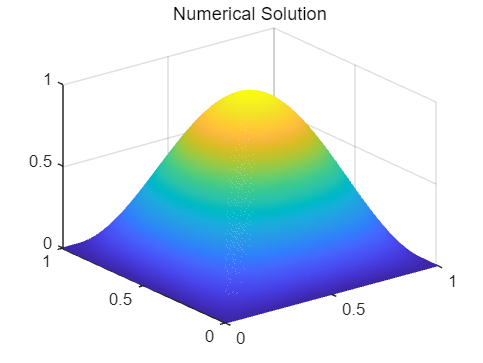

[X, Y] = meshgrid(0:h:1, 0:h:1);

Z = sin(pi * X) .* sin(pi * Y);

mesh(X, Y, sol)
title("Numerical Solution")

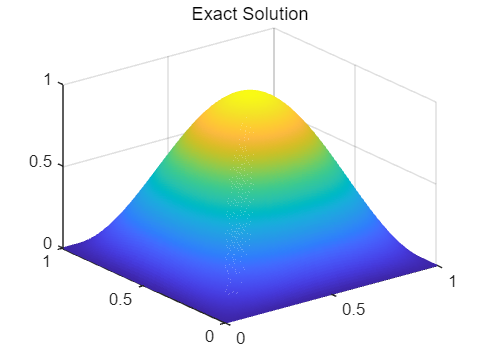

mesh(X, Y, Z)
title("Exact Solution")

## 2

N = 75;
L = 1.0;
h = L / (N - 1);

a = @(x, y) sin(x);
b = @(x, y) cos(x + y);
c = @(x, y) sin(y);
aij = @(i, j) a((i - 1) * h, (j - 1) * h);
bij = @(i, j) b((i - 1) * h, (j - 1) * h);
cij = @(i, j) c((i - 1) * h, (j - 1) * h);

alloc = @(i, j) (i - 1) * N + j;
A = GenerateCoeffMatrix2(N, h, aij, bij, cij, alloc);

sz = size(A);
rhs = zeros(sz(1), 1);

for k = 1 : N
    rhs(alloc(k, 1)) = 0;
    rhs(alloc(k, N)) = 1 / h ^ 2;
    rhs(alloc(1, k)) = 0;
    rhs(alloc(N, k)) = 1 / h ^ 2;
end

% 5 points
maxit = 1000;
%sol = LinSolver.Solve( A, rhs );
%[L,U] = ilu(A,struct('type','ilutp','droptol',1e-6));
%[sol, flag, relres, iter, resvec] = gmres(A, rhs, [], 1e-10, maxit, L, U);
[sol, ~, ~, ~, ~] = gmres(A, rhs, [], 1e-10, maxit, [], []);
sol = reshape(sol, [N N]);

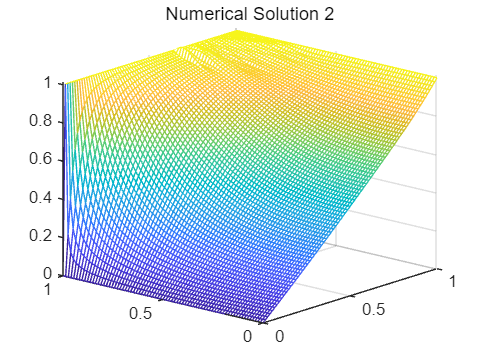

[X, Y] = meshgrid(0:h:1, 0:h:1);

mesh(X, Y, sol)
title("Numerical Solution 2")

## 3

N = 100;
L = 1.0;
h = L / (N - 1);

x = @(i) (i - 1) * h;

alloc = @(i, j) (i - 1) * N + j;
A = GenerateCoeffMatrix3(N, h, x, alloc);

sz = size(A);
rhs = zeros(sz(1), 1);

for k = 1 : N
    rhs(alloc(k, 1)) = 0;
    rhs(alloc(k, N)) = 1 / h ^ 2;
    rhs(alloc(1, k)) = 0;
    rhs(alloc(N, k)) = 1 / h ^ 2;
end

% 5 points
maxit = 1000;
%sol = LinSolver.Solve( A, rhs );
%[L,U] = ilu(A,struct('type','ilutp','droptol',1e-6));
%[sol, flag, relres, iter, resvec] = gmres(A, rhs, [], 1e-10, maxit, L, U);
[sol, flag, relres, iter, resvec] = gmres(A, rhs, [], 1e-10, maxit, [], []);
sol = reshape(sol, [N N]);

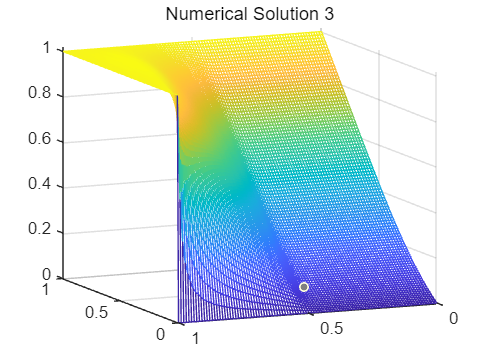

[X, Y] = meshgrid(0:h:1, 0:h:1);

mesh(X, Y, sol)
title("Numerical Solution 3")

function A = GenerateCoeffMatrix5Point(N, h, allocator)
    nonzero_size = (N - 2) * (N - 2) * 5 + 4 * N - 4;
    ids_row = zeros(1, nonzero_size);
    ids_col = zeros(1, nonzero_size);

    values = zeros(1, nonzero_size);

    row = 1;
    count = 1;
    for i = 1:N
        for j = 1:N
        if i ~= 1 && i ~= N && j ~= 1 && j ~= N
            ids_row(count) = row;
            ids_col(count) = allocator(i - 1, j);
            values(count) = 1 / h^2;
            count = count + 1;

            ids_row(count) = row;
            ids_col(count) = allocator(i + 1, j);
            values(count) = 1 / h^2;
            count = count + 1;

            ids_row(count) = row;
            ids_col(count) = allocator(i, j - 1);
            values(count) = 1 / h^2;
            count = count + 1;

            ids_row(count) = row;
            ids_col(count) = allocator(i, j + 1);
            values(count) = 1 / h^2;
            count = count + 1;
        end

        % center
        ids_row(count) = row;
        ids_col(count) = allocator(i, j);
        values(count) = -4 / h^2;
        count = count + 1;

        % next equation
        row = row + 1;
        end
    end

    A = sparse(ids_row, ids_col, values);
end

function A = GenerateCoeffMatrix2(N, h, a, b, c, allocator)
    nonzero_size = (N - 2) * (N - 2) * 5 + 5 * N - 4;
    ids_row = zeros(1, nonzero_size);
    ids_col = zeros(1, nonzero_size);

    values = zeros(1, nonzero_size);

    row = 1;
    count = 1;
    for i = 1:N
        for j = 1:N
        if i ~= 1 && i ~= N && j ~= 1 && j ~= N
            ids_row(count) = row;
            ids_col(count) = allocator(i - 1, j);
            values(count) = (b(i-1,j)-b(i+1,j)+4*b(i,j))/(4*h^2);
            count = count + 1;

            ids_row(count) = row;
            ids_col(count) = allocator(i + 1, j);
            values(count) = (b(i+1,j)-b(i-1,j)+4*b(i,j))/(4*h^2);
            count = count + 1;

            ids_row(count) = row;
            ids_col(count) = allocator(i, j - 1);
            values(count) = (a(i-1,j)-a(i+1,j)+4*a(i,j))/(4*h^2)-c(i,j)/(2*h);
            count = count + 1;

            ids_row(count) = row;
            ids_col(count) = allocator(i, j + 1);
            values(count) = (a(i+1,j)-a(i-1,j)+4*a(i,j))/(4*h^2)+c(i,j)/(2*h);
            count = count + 1;
        end

        % center
        ids_row(count) = row;
        ids_col(count) = allocator(i, j);
        if i == 1 || i == N || j == 1 || j == N
            values(count) = 1 / h^2;
        else
            values(count) = -(2 * a(i, j) + 2 * b(i, j)) / h^2;
        end
        count = count + 1;

        if j == 1
            ids_row(count) = row;
            ids_col(count) = allocator(i, j + 1);
            values(count) = -1/h^2;
            count = count + 1;
        end

        % next equation
        row = row + 1;
        end
    end

    A = sparse(ids_row, ids_col, values);
end

function A = GenerateCoeffMatrix3(N, h, x, allocator)
    nonzero_size = (N - 2) * (N - 2) * 5 + 5 * N - 4;
    ids_row = zeros(1, nonzero_size);
    ids_col = zeros(1, nonzero_size);

    values = zeros(1, nonzero_size);

    row = 1;
    count = 1;
    for i = 1:N
        for j = 1:N
        if i ~= 1 && i ~= N && j ~= 1 && j ~= N
            ids_row(count) = row;
            ids_col(count) = allocator(i - 1, j);
            values(count) = x(i) / h ^ 2;
            count = count + 1;

            ids_row(count) = row;
            ids_col(count) = allocator(i + 1, j);
            values(count) = x(i) / h ^ 2;
            count = count + 1;

            ids_row(count) = row;
            ids_col(count) = allocator(i, j - 1);
            values(count) = -1/(2*h);
            count = count + 1;

            ids_row(count) = row;
            ids_col(count) = allocator(i, j + 1);
            values(count) = 1/(2*h);
            count = count + 1;
        end

        % center
        ids_row(count) = row;
        ids_col(count) = allocator(i, j);
        if i == 1 || i == N || j == 1 || j == N
            values(count) = 1 / h^2;
        else
            values(count) = -2 * x(i) / h ^ 2;
        end
        count = count + 1;

        if j == 1
            ids_row(count) = row;
            ids_col(count) = allocator(i, j + 1);
            values(count) = -1/h^2;
            count = count + 1;
        end

        % next equation
        row = row + 1;
        end
    end

    A = sparse(ids_row, ids_col, values);
end